clear all;
close all;
clc;
[erfuellt] = check_dependencies();



Hinweis: Ordner .\software wurde für diese Session zum Pfad hinzugefügt.


Gefundene .XLSX Datei(en): FEF_activations_Bedini_2021_and_iFEF.xlsx


SPM ist installiert und erreichbar



Alle nötigen Abhängigkeiten erfüllt!



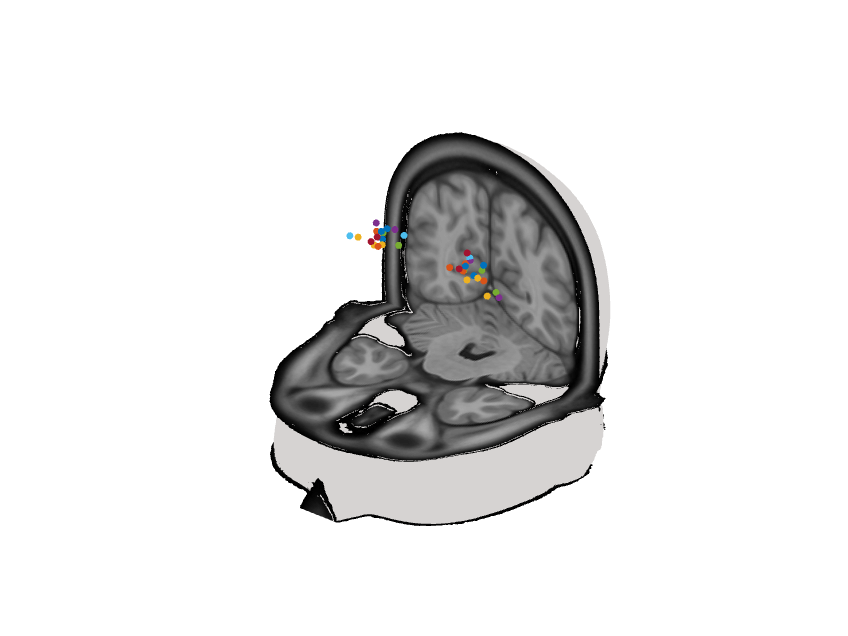

[hfig, template, template_vol] = visualize_template();

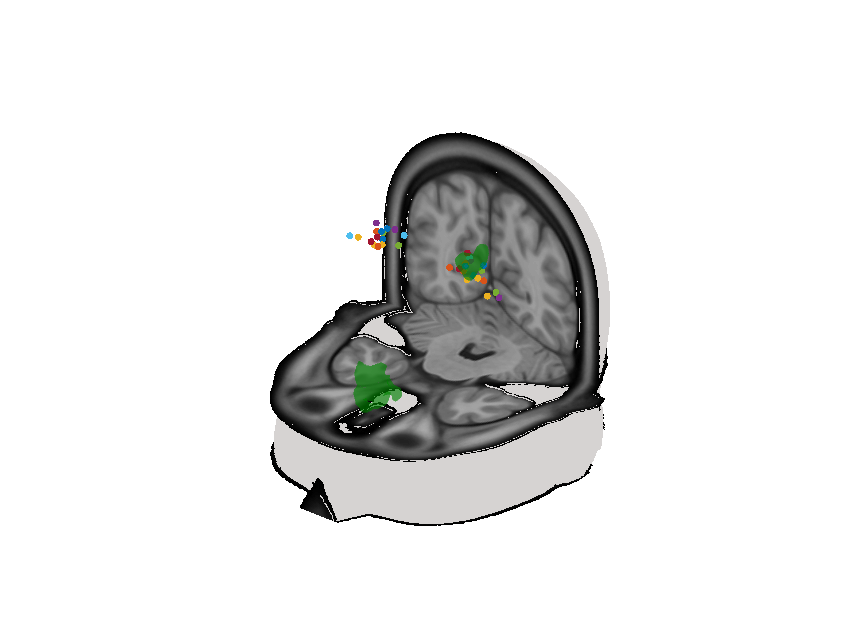

hfig = plot_excel_data_on_figure(hfig,template,'FEF_activations_Bedini_2021_and_iFEF.xlsx');

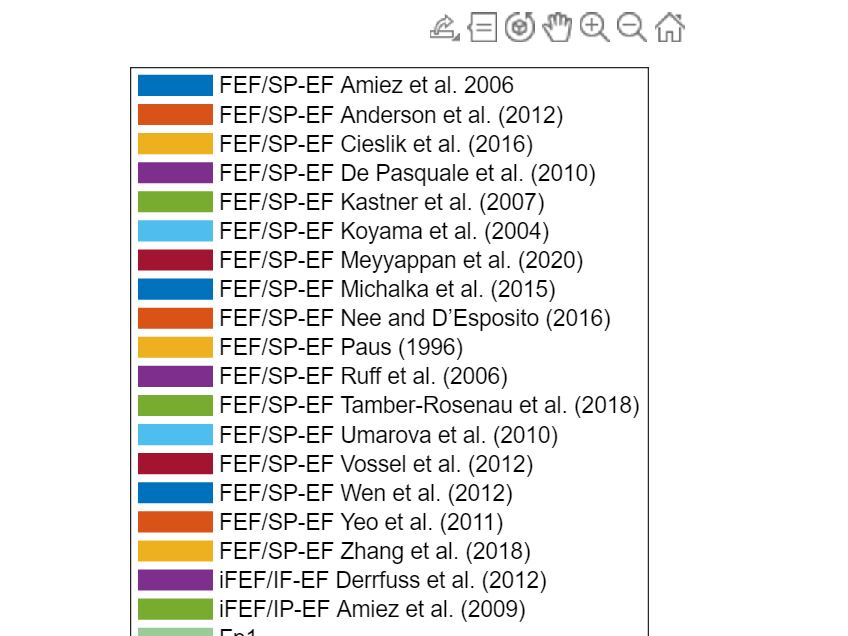

% kann für beliebig viele pmaps wiederholt werden
[hfig, h_patch_Fp1] = plot_isosurface(hfig, 'Area-Fp1_pmap_l_N10_nlin2ICBM152asym2009c.nii', 'Fp1');
[hfig, h_patch_6v2] = plot_isosurface(hfig, '6v2_l.nii', '6v2_l');

%es werde Licht
camlight(40, 40);
camlight(-20, -10);
lighting gouraud;

edit_legend()

**Ab hier keine Änderung vornehmen!!!**

function [isDependenciesMet] = check_dependencies()
    % check_dependencies überprüft, ob alle erforderlichen Abhängigkeiten für das ausführende Skript vorhanden sind.
    % Dazu gehören spezifische Ordner und Dateien im Dateisystem sowie die Installation der SPM12 Toolbox.
    %
    % Ausgabe:
    % isDependenciesMet - Ein logischer Wert, der angibt, ob alle Abhängigkeiten erfüllt sind (true) oder nicht (false).
    %   Die Funktion gibt 'true' zurück, wenn:
    %   - Alle erforderlichen Ordner im Dateisystem vorhanden sind.
    %   - Die Datei 'mni_icbm152_t1_tal_nlin_asym_09c.nii' im Ordner 'template_volume' vorhanden ist.
    %   - Mindestens eine .XLSX-Datei im Ordner 'coordinate_files' vorhanden ist.
    %   - Mindestens eine .nii-Datei im Ordner 'orig_volume_as_nifti' vorhanden ist.
    %   - Die SPM12 Toolbox im MATLAB-Pfad installiert ist.
    %   Wenn eine dieser Bedingungen nicht erfüllt ist, gibt die Funktion 'false' zurück.
    %
    % Beispielaufruf:
    % [erfüllt] = check_dependencies()

    % Definieren Sie die erforderlichen Pfade
    softwareFolder = fullfile('.', 'software');
    requiredFolders = {
        softwareFolder, 
        fullfile('.', 'input_data'), 
        fullfile('.', 'input_data', 'template_volume'), 
        fullfile('.', 'input_data', 'orig_volume_as_nifti'), 
        fullfile('.', 'input_data', 'processed_volume_as_nifti'), 
        fullfile('.', 'input_data', 'coordinate_files')
    };
    templateFile = fullfile('.', 'input_data', 'template_volume', 'mni_icbm152_t1_tal_nlin_asym_09c.nii');

    % Überprüfen, ob der software-Ordner im Pfad ist
    if ~exist(softwareFolder, 'dir')
        fprintf('\nFehler: Ordner %s nicht gefunden.\n', softwareFolder);
        isDependenciesMet = false;
        return;
    elseif ~contains(path, softwareFolder)
        addpath(softwareFolder);
        fprintf('\n\nHinweis: Ordner %s wurde für diese Session zum Pfad hinzugefügt.\n', softwareFolder);
    end

    % Überprüfen Sie, ob alle anderen Ordner vorhanden sind
    for i = 2:length(requiredFolders)
        if ~exist(requiredFolders{i}, 'dir')
            fprintf('\nFehler: Ordner %s nicht gefunden.\n', requiredFolders{i});
            isDependenciesMet = false;
            return;
        end
    end

    % Überprüfen Sie die spezifischen Dateien in den Ordnern
    if ~exist(templateFile, 'file')
        fprintf('Fehler: Datei %s nicht gefunden.\n', templateFile);
        isDependenciesMet = false;
        return;
    end

    % Überprüfen Sie auf mindestens eine .XLSX-Datei im Ordner coordinate_files
    if isempty(dir(fullfile(requiredFolders{6}, '*.xlsx')))
        fprintf('Fehler: Keine .XLSX Datei im Ordner %s gefunden.\n', requiredFolders{6});
        isDependenciesMet = false;
        return;
    else
        xlsxFiles = dir(fullfile(requiredFolders{6}, '*.xlsx'));
        fprintf('\n\nGefundene .XLSX Datei(en): %s\n', strjoin({xlsxFiles.name}, ', '));
    end

    % Überprüfen Sie auf mindestens eine .nii-Datei im Ordner orig_volume_as_nifti
    if isempty(dir(fullfile(requiredFolders{4}, '*.nii')))
        fprintf('\n\nFehler: Keine .nii Datei im Ordner %s gefunden. Evtl. .gz Datei? Dann zuerst entpacken\n', requiredFolders{4});
        isDependenciesMet = false;
        return;
    end

    % Überprüfen, ob die SPM12 Toolbox installiert ist
    if ~exist('spm', 'file')
        fprintf('Fehler: SPM12 Toolbox ist nicht installiert oder nicht im MATLAB-Pfad.\n');
        isDependenciesMet = false;
        return;
    else
        fprintf('\n\nSPM ist installiert und erreichbar\n\n');
    end

    % Wenn alle Überprüfungen bestanden sind
    isDependenciesMet = true;
    if isDependenciesMet == true
        fprintf('\n\nAlle nötigen Abhängigkeiten erfüllt!\n\n');
    end
end
